exercise 1

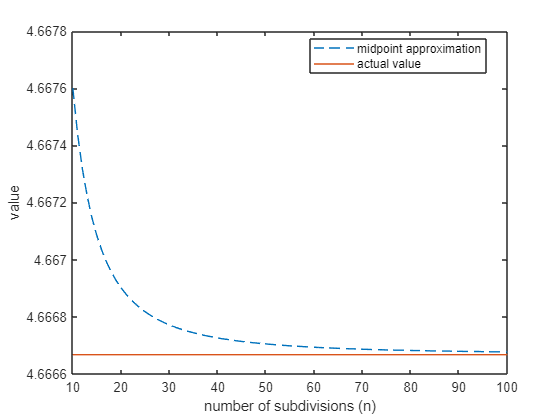

clc;
clear;
close all;

first = 10;
last = 100;

a = 0;
b = 3;

mid_sums = [];
errors = [];
upper_bound = [];

for n = first:last
    delta_x = (b-a)/n;

    x_vals = linspace(a+(delta_x/2), b-(delta_x/2), n);
    approx = sum(sqrt(x_vals + 1) * delta_x);    

    mid_sums(n-(first-1)) = approx;
    errors(n-(first-1)) = abs(approx - 14/3);
    upper_bound(n-(first-1)) = (((b-a)^3)*0.25)/(24*n^2);
end

x = 10:100;

figure;

subplot;
plot(x, mid_sums, LineStyle="--");
hold on;
plot(x, ones(1, last-first+1).*14/3);
legend("midpoint approximation", "actual value", location="best");
xlabel("number of subdivisions (n)");
ylabel("value");

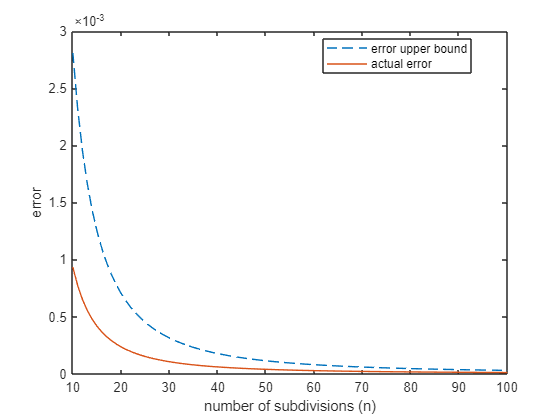


subplot;
plot(x, upper_bound, LineStyle="--");
hold on;
plot(x, errors);
legend("error upper bound", "actual error", location="best");
xlabel("number of subdivisions (n)");
ylabel("error");

exercise 2

clc;
clear;
close all;

first = 10;
last = 100;

a = 0;
b = 3;

trap_sums = [];
errors = [];
upper_bound = [];

for n = first:last
    delta_x = (b-a)/n;

    left_x_vals = linspace(a, b-delta_x, n);
    right_x_vals = linspace(a+delta_x, b, n);

    l = sqrt(left_x_vals + 1);
    r = sqrt(right_x_vals + 1);
    
    approx = sum((l + r) /2) * delta_x;

    mid_sums(n-(first-1)) = approx;
    errors(n-(first-1)) = abs(approx - 14/3);
    upper_bound(n-(first-1)) = (((b-a)^3)*0.25)/(12*n^2);
end

x = 10:100;

figure;

subplot;
plot(x, mid_sums, LineStyle="--");
hold on;
plot(x, ones(1, last-first+1).*14/3);
legend("trapezoidal approximation", "actual value", location="best");
xlabel("number of subdivisions (n)");
ylabel("value");

subplot;
plot(x, upper_bound, LineStyle="--");
hold on;
plot(x, errors);
legend("error upper bound", "actual error", location="best");
xlabel("number of subdivisions (n)");
ylabel("error");